clear
close all
clc

Øvelse af anvendelsen af MATLAB til design og analyse af digitale FIR-filtre.

## Eksempel 1: FIR-båndpasfilter med Hamming-vindue:

Der ønskes konstrueret et digitalt FIR-båndpasfilter med Hamming-vindue ved anvendelse af "Window"-metoden.

Der tages udgangspunkt i et ideelt båndpasfilter, der sampler med fs = 8000.

Den nedre pasbåndsfrekvens er 1,4 kHz, mens den øvre er 2,6 kHz. Midten er således ved 2 kHz. Til dimensionering af filteret defineres følgende værdier:

fs = 8000;

fsl = 1000; % Nedre stopbånd = 1000 Hz
fpl = 1800; % Nedre pasbånd = 1800 Hz
fpu = 2200; % Øvre pasbånd = 2200 Hz
fsu = 3000; % Øvre stopbånd = 3000 Hz
As = 50; % Dæmpning i stopbånd = 50 dB

**Opgave 1a) Brug en tabel til at finde ud af, om Hamming-vinduet kan anvendes med de stillede krav. Udregn manuelt med tabel filterordenen N-1 ud fra de stillede krav til overgangsområderne. Rund op, så filterordenen N-1 bliver heltallig og lige, dvs. filterlængden N ulige.**

Tabellen 7.7 i Digital Signal Processing (side 241) viser, at Hamming-vinduet dæmper med 53 dB, og det kan derfor anvendes. Den krævede filterorden udregnes:

delta_f = abs(fsl-fpl)/fs;
N = 3.3/delta_f

N = 33.0000

Ord = N-1

Ord = 32.0000

Filteret skal altså være af 32. orden.

**Opgave 1b) Find filterkoefficienterne ved Fourier-koefficientmetoden. Hvad er H(z)?**

Der anvendes kommandoen fir1:

f1 = (fsl+fpl)/2;
f2 = (fsu+fpu)/2;
b = fir1(floor(Ord),[f1/(fs/2) f2/(fs/2)], hamming(floor(N)))

b =     0.0020   -0.0014   -0.0003   -0.0022   -0.0066    0.0123    0.0175   -0.0189   -0.0129   -0.0035   -0.0316    0.0698    0.1136   -0.1562   -0.1901    0.2089    0.2089   -0.1901   -0.1562    0.1136    0.0698   -0.0316   -0.0035   -0.0129   -0.0189    0.0175    0.0123   -0.0066   -0.0022   -0.0003   -0.0014    0.0020


Koefficienterne er nu fundet.

Hz = tf(b,1,-1)


Hz =
 
                                                                                                     
  0.001974 z^31 - 0.001445 z^30 - 0.0003057 z^29 - 0.002231 z^28 - 0.006616 z^27 + 0.01232 z^26      
                                                                                                     
          + 0.01746 z^25 - 0.01887 z^24 - 0.01289 z^23 - 0.003548 z^22 - 0.03164 z^21 + 0.06982 z^20 
                                                                                                     
          + 0.1136 z^19 - 0.1562 z^18 - 0.1901 z^17 + 0.2089 z^16 + 0.2089 z^15 - 0.1901 z^14        
                                                                                                     
          - 0.1562 z^13 + 0.1136 z^12 + 0.06982 z^11 - 0.03164 z^10 - 0.003548 z^9 - 0.01289 z^8     
                                                                                                     
          - 0.01887 z^7 + 0.01746 z^6 + 0.01232 z^5 - 0.006616 z^4 - 0.002

**Opgave 1c) Kontroller, at filteret faktisk er FIR Type 1.**

Dette gøres ved at plotte koefficienterne og se, om de er symmetriske om y-aksen.

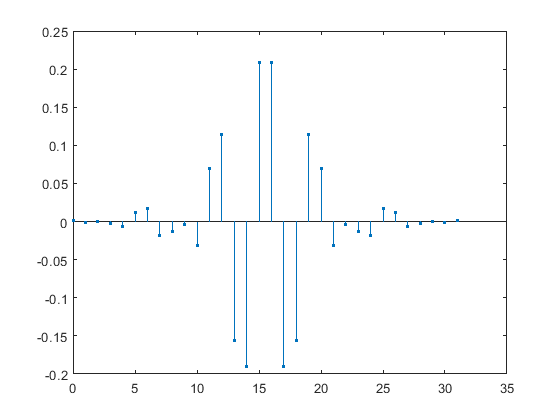

n=0:(N-1); stem(n,b,'.')

Dette er de, og det er derfor en FIR Type 1.

**Opgave 1d) Kontroller, at kravene til filteret er opfyldt. Afbild poler, nulpunkter og gruppeløbetid.**

Gøres med freqz, zplane og grpdelay.

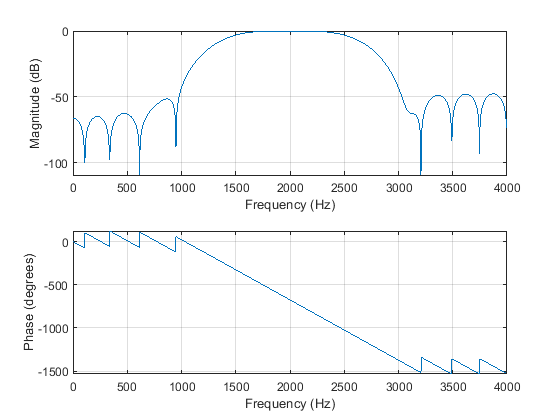

freqz(b,1,1024,fs)

Kravene er opfyldt, og fasen er lineær.

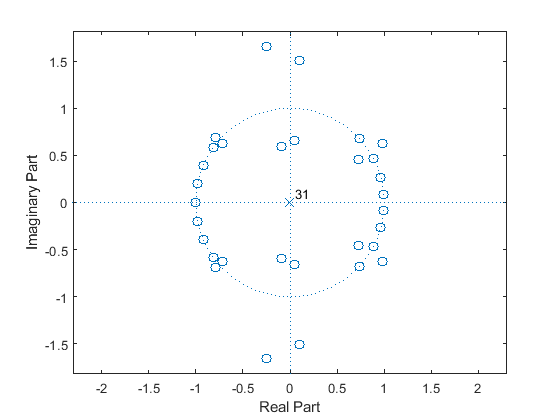

zplane(b,1)

Det kan ses, at der er poler rundt om frekvenserne 1000-3000, hvilket forårsager båndstoppet udenfor dette område.

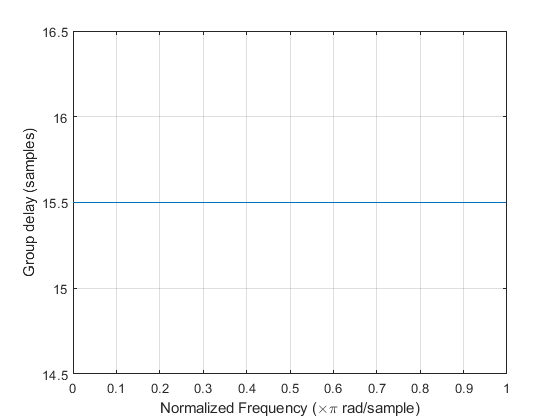

grpdelay(b,1)

Gruppeløbetiden er konstant.

## Eksempel 2: FIR-båndpasfilter med Kaiser-vindue

Her anvendes i stedet et Kaiser-vindue til at lave det samme filter som i eksempel 1.